**Цель работы:** изучение моделей линейных непрерывных систем и их элементов с постоянными параметрами, знакомство с временными и частотными характеристиками.

**Порядок выполнения работы**

1.     Записать передаточную функцию и tf-модель исследуемого звена. 

-Интегрирующее звено $\omega \left(S\right)=\frac{K}{S}$

k=24;
w1=tf(k,[1 0])


w1 =
 
  24
  --
  s
 
Continuous-time transfer function.



-Апериодическое звено $T\frac{dy}{dt}+y=ku\left(t\right)$

T=0.1*k;
w2=tf(k,[T 1]) 


w2 =
 
     24
  ---------
  2.4 s + 1
 
Continuous-time transfer function.



-Интегродифференцирующее $\omega \left(s\right)=\frac{K\left(T1s+1\right)}{T2s+1}$

T1=T;
T2=10*T;
w3=tf([k*T1 k], [T2 1])


w3 =
 
  57.6 s + 24
  -----------
   24 s + 1
 
Continuous-time transfer function.



-Колебательное $T^2 \frac{d^2 y}{dt^2 }+2\xi T\frac{dy}{dt}+y\left(t\right)=ku\left(t\right)$

xi=0.8;
w4=tf(k, [T^2 2*xi*T 1])


w4 =
 
           24
  ---------------------
  5.76 s^2 + 3.84 s + 1
 
Continuous-time transfer function.



2.     Исследовать влияние параметров каждого из звеньев на временные и частотные характеристики.

w1_1=tf(10*k, [1 0])


w1_1 =
 
  240
  ---
   s
 
Continuous-time transfer function.



2.1.1 Исследовать влияние k(коэффициента усиления) интегрирующего звена;

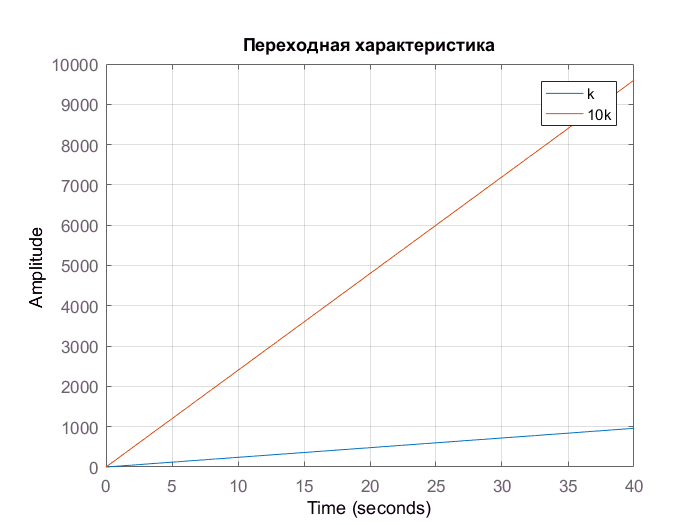

figure, step(w1, w1_1), grid on
title('Переходная характеристика'), legend('k','10k')

Вывод: при увеличении коэффициента усиления увеличивается угол наклона переходной характеристики

2.1.2 Исследовать влияние k и Т апериодического звена;

w2_1=tf(5*k, [T 1])


w2_1 =
 
     120
  ---------
  2.4 s + 1
 
Continuous-time transfer function.



w2_2=tf(k,[5*T 1])


w2_2 =
 
     24
  --------
  12 s + 1
 
Continuous-time transfer function.



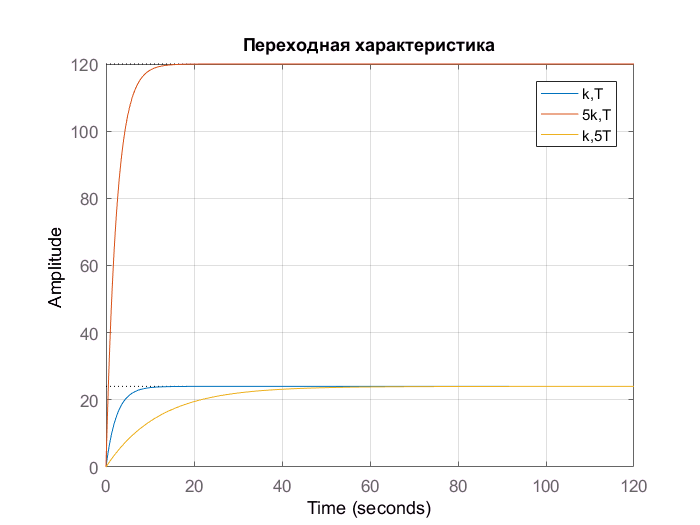

figure, step(w2, w2_1, w2_2), grid on, title('Переходная характеристика'), legend('k,T', '5k,T', 'k,5T')

Вывод: при увеличении коэффициента усиления увеличивается установившееся значения переходной характерсистики, а длительность процесса не изменяется. При увеличении постоянной времени увеличивается длительность перехода процесса, а установившееся значение остаётся неизменной

2.1.3 Исследовать влияние колебательного звена;

w4_1=tf(k, [T^2 4*xi*T 1])


w4_1 =
 
           24
  ---------------------
  5.76 s^2 + 7.68 s + 1
 
Continuous-time transfer function.



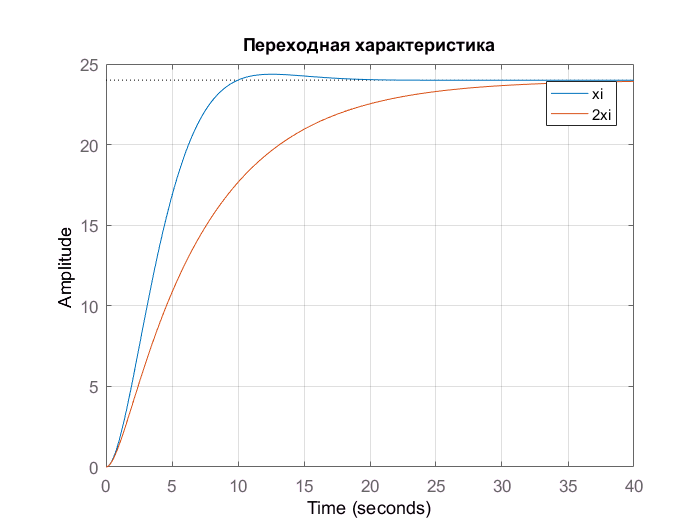

figure, step(w4, w4_1), grid on, title('Переходная характеристика'), legend('xi', '2xi')

Вывод: при увеличении коэффициента коллебательности переходной процесс становится менее коллебательным, уменьшается длительность переходного процесса, а уровень установившегося значения остаётся неизменным

2.1.4 Для интегродифференцирующего звена создать 2 модели с соотношениями Т1<T2 и T1>T2.

w3_1=tf([k*T2 k], [T1 1])


w3_1 =
 
  576 s + 24
  ----------
  2.4 s + 1
 
Continuous-time transfer function.



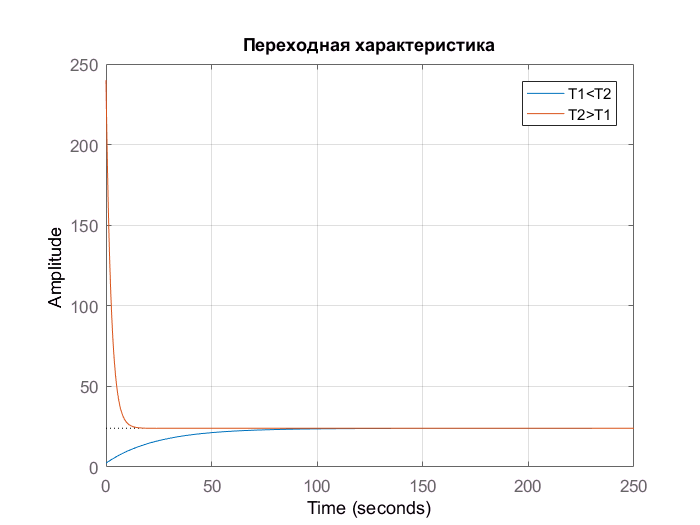

figure, step(w3, w3_1), grid on, title('Переходная характеристика'), legend('T1<T2', 'T2>T1')

2.2. Выяснить влияние параметров звеньев на вид АЧХ, ФЧХ и АФЧХ, осуществляя построение *L*(*ω*) , *j*(*ω*)  и *w*(*j**ω*) для нескольких моделей в одном окне, используя команды  *bode*(*w*1, *w*2) и  *nyquist*(*w*1, *w*2).

2.2.1 Исследовать влияние k(коэффициента усиления) интегрирующего звена;

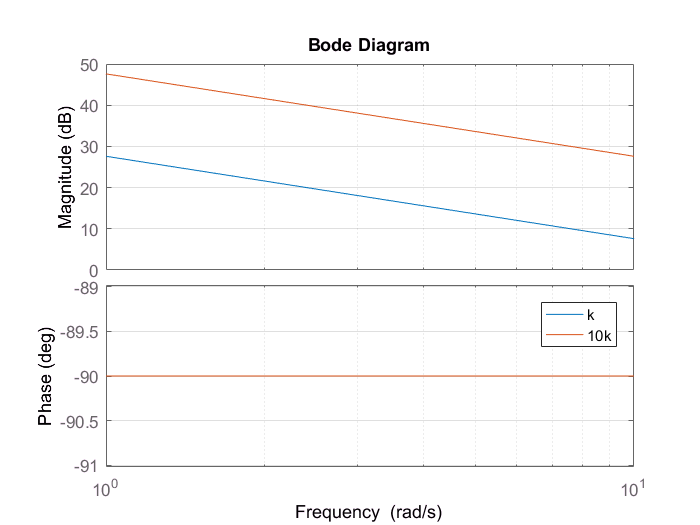

figure, bode(w1, w1_1), grid on, legend('k','10k')

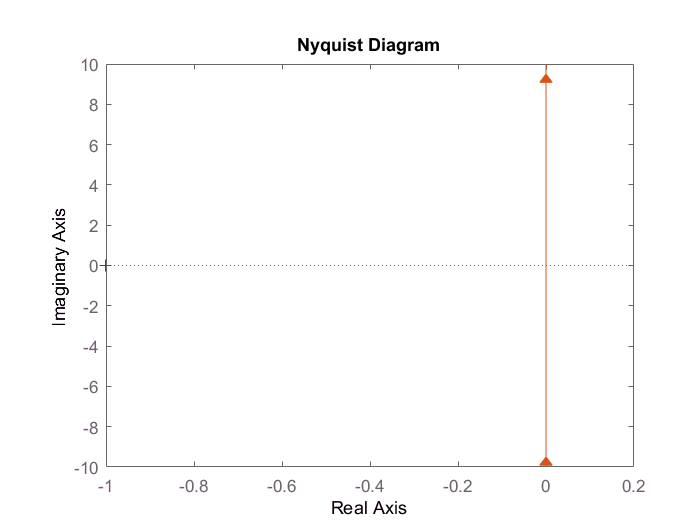

figure, nyquist(w1,w1_1)

Вывод: при увеличении коэффициента усиления увеличивается частота среза, фазовый сдвиг остаётся неизменным и равным 90 градусов

2.2.2 Исследовать влияние k и Т апериодического звена;

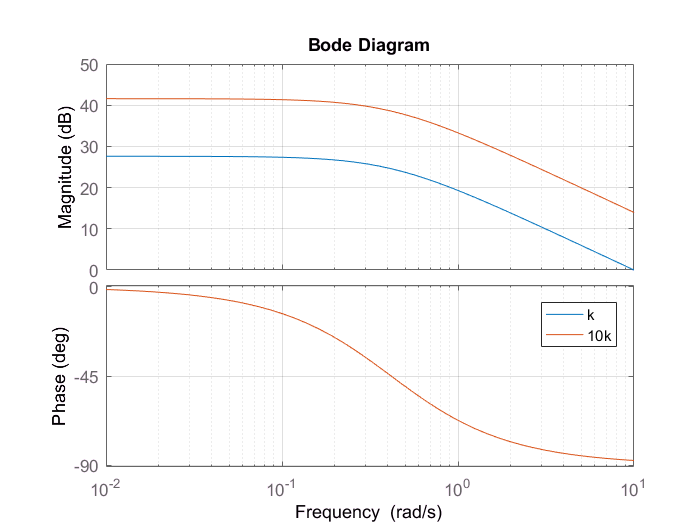

figure, bode(w2, w2_1), grid on, legend('k','10k')

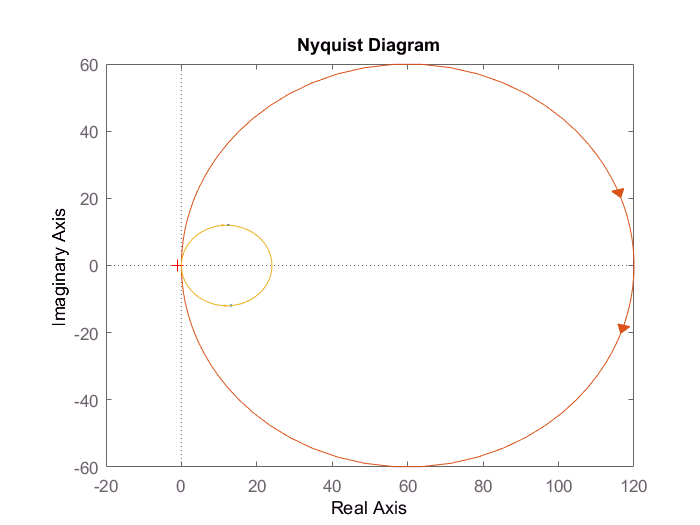

figure, nyquist(w2, w2_1, w2_2)

Вывод: при увеличении коэффициента усиления увеличивается частота среза, а фазовый сдвиг не изменяется, при увеличении коэффициента постоянной времени частота среза уменьшается, а фазовый сдвиг уменьшается.

2.2.3. Исследовать влияние колебательного звена;

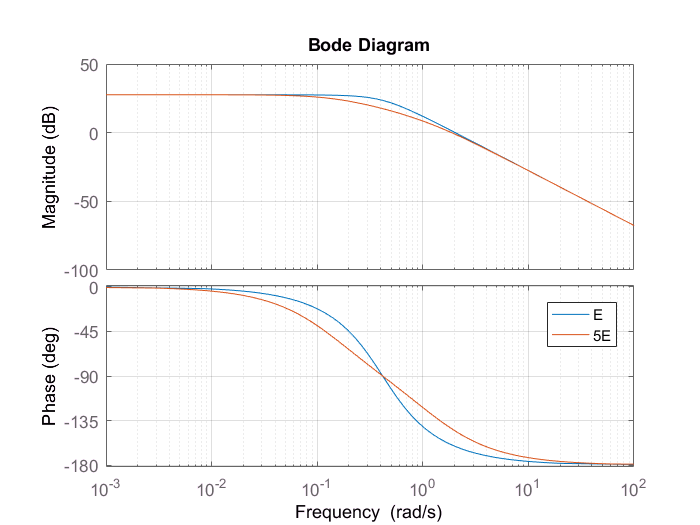

figure, bode(w4, w4_1), grid on, legend('E','5E')

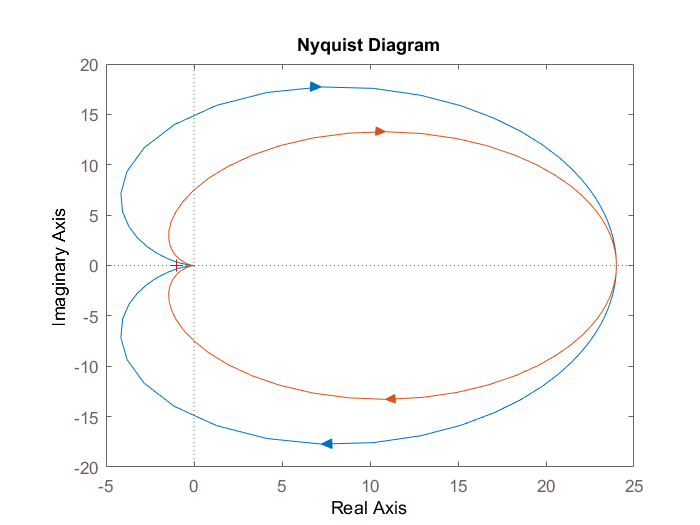

figure, nyquist(w4, w4_1)

Вывод: при увеличении коэффициента деформирования частота среза только убывает, график фазы становится плавным и на некоторой частоте обе линии графиков имеют точку пересечения.

2.2.4. Для интегродифференцирующего звена создать 2 модели с соотношениями   Т1<T2 и T1>T2.

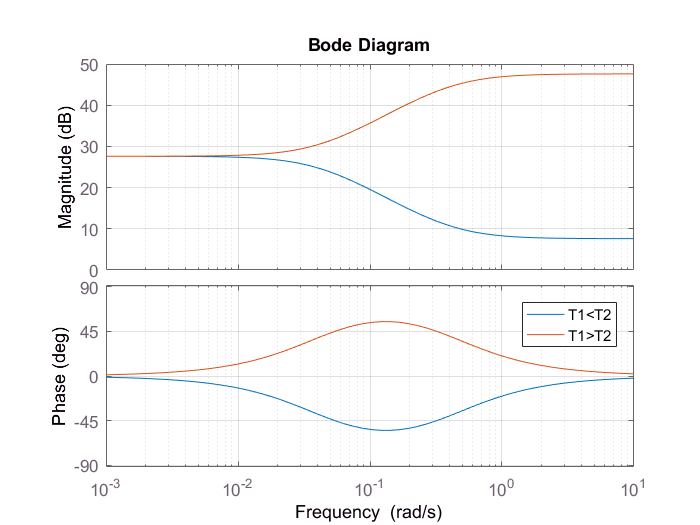

figure, bode(w3,w3_1), grid on, legend('T1<T2','T1>T2')

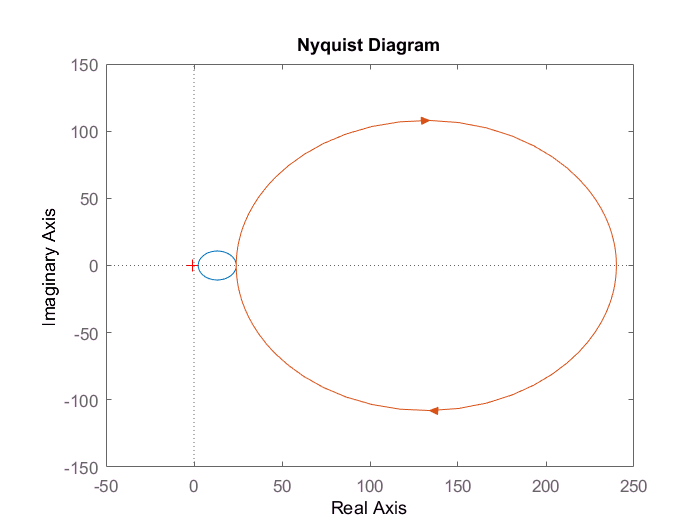

figure, nyquist(w3, w3_1)

w = tf([288 144], [1 15 68 96])


w =
 
        288 s + 144
  ------------------------
  s^3 + 15 s^2 + 68 s + 96
 
Continuous-time transfer function.



ss(w)